# Analise e sintese de Fourier

clear all;      
close all;      
clc;


## Modelando o sinal g(t)

A1 = 1;
A2 = 0;
tau1 = 0.5;
tau2 = 0.5;

To = tau1 + tau2;
fo = inv(To);
wo = 2*pi/To;



## Cálculo das projeções

syms n t
%%% Parte da integral com cosseno (Projeção)
Ipc = int(A1 * cos(n*wo*t),t,0,tau1)

$$Ipc = \frac{\sin\left(\pi \,n\right)}{2\,n\,\pi }$$

Inc = int(A2 * cos(n*wo*t),t,tau1,To)

$$Inc = 0$$

an = Ipc + Inc

$$an = \frac{\sin\left(\pi \,n\right)}{2\,n\,\pi }$$

%%% Parte da integral com seno (Projeção)
Ips = int(A1 * sin(n*wo*t),t,0,tau1)

$$Ips = \frac{{\sin\left(\frac{\pi \,n}{2}\right)}^{2}}{n\,\pi }$$

Ins = int(A2 * sin(n*wo*t),t,tau1,To)

$$Ins = 0$$

bn = Ips + Ins

$$bn = \frac{{\sin\left(\frac{\pi \,n}{2}\right)}^{2}}{n\,\pi }$$

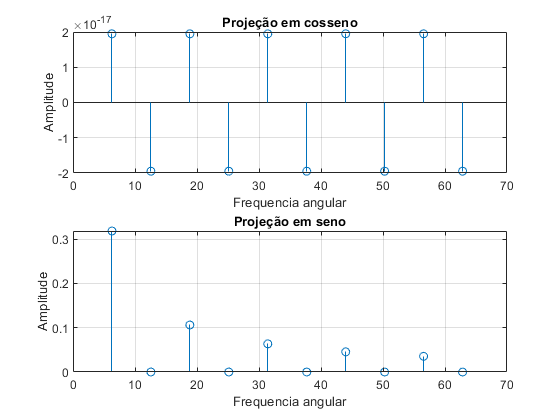

%%% Determinando os valores numericos
N = 10;
n = [1:1:N];

a = eval(an);
b = eval(bn);

%%% Grafico dos valores
figure(1)
subplot(2,1,1); stem(n*wo,a);
grid; 
title('Projeção em cosseno');
xlabel('Frequencia angular');
ylabel('Amplitude');

subplot(2,1,2); stem(n*wo,b);
grid; 
title('Projeção em seno');
xlabel('Frequencia angular');
ylabel('Amplitude');

%%% o sinal somente tem termos (projeçã) em seno
%%% e as projeções em cosseno são nulas


## Sintese de Fourier

auxc = 0;
auxs = 0;
R = To/1000; %%% Resolução do sinal no tempo (qtde de pontos)
tempo = [0:R:To]

tempo =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


for k=1:N
    
    auxc = auxc + a(k)*cos(n(k)*wo*tempo);
    auxs = auxs + b(k)*sin(n(k)*wo*tempo);
end
a0 = (A1*tau1 + A2*tau2)/To;

a0 = 0.5000

gt = a0 + auxc + auxs; %%% Somatoria de Fourier
qt = square(tempo, 50);

figure(2)
plot(tempo,gt); hold; plot(tempo,qt);

Current plot held


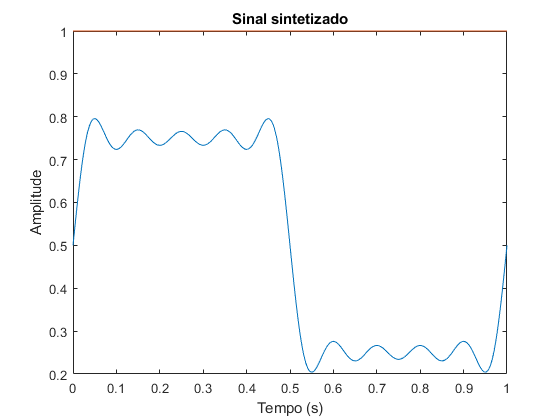

title('Sinal sintetizado');
xlabel('Tempo (s)');
ylabel('Amplitude');